# Modelling House Prices

Recapping the Exploratory Data Analysis;

**EDA Insights;**

- "Apartments with equivalent features (`bathrooms`, `garages `etc.) sell for different prices with only `sale_date `changing. Once `sale_date` is controlled for, the remaining variance could give a benchmark for the external effects on `sale_price `that we do not have data for."

- "`sale_price` and `year_built` have a weak relationship with occurance of missing values, but `sale_price` and `year_built` themselves have a strong relationship."

- "Missing value rows occur very slightly more with properties built more recently."

- *"*sale_price is positively skewed."

**Data Notes;**

- `floorplate, land `& `max_roof_height` could be multi modal.

- `For ``property_type="``Strata``", floorplate, land `& `max_roof_height` are not unique to an observation, only to `property_id`.

- `bedroom, bathroom, garage` are collinear, and positively correlated with `sale_price`

- `year_built `has significantly more observations at start of each decade. In the absense of subject matter expert to consult, this is likely measurement error.

- `slope` is completely independent of `sale_price`

**Modelling implications;**

- `sale_date`'s effect on `sale_price` is an effect within the group of `property_id`. 

- `year_built` is a good proxy to downweight observations uniformly due to mising data pattern, and specifically for `year_built `at the satart of decades.

- log transform for `sale_price.`

- `max_roof_height`, `land `& `floorplate` needs interaction terms to capture their multi-modal distribution.

- use `property_id `to impute missing values exactly.

- `bedroom, bathroom, garage `can be treated as ordinal variables.

**Variable Types:**

The indepenedent variables likely to be predictive of sale_price are a range of types;

- fixed effects categorical: state, property_type

- random effects categorical: postcode(nested in state), suburb(nested in postcode, state).

- ordinal: `bedrooms, bathrooms, garages`.

- continuous: `floorplate, max_roof_height.`

Fixed categoricals can be converted to dummy variables, random categoricals should utilise modelling methods' treatment, else there will be too many terms.

Ordinal variables could be converted to numeric continuous for simplicity & to allow prediction outside the range in the dataset.

## Feature Engineering;

Feature engineering has been done in the EDA in this case. 

## Splitting data into train, test and validation sets

because multiple models will be tested, a test set is required to select the best one. Validation set will also be used to fine tune each model's hyperparameters.

% create train & test split 70%-30%
[trainId,testId] = crossvalind('LeaveMOut' , 52248 , floor(52248*0.3) );
% create validation split 15%
validateId = false(size(testId));
tstrw = find( testId );
tstrw = tstrw(randperm(numel(tstrw)));
validateId( tstrw( 1:floor(numel(tstrw)/2) ) ) = true;
% remove validation split from test set
testId = testId & ~validateId;
disp( sum([trainId, testId , validateId]) )

       36574        7837        7837


## Model 0: removed all rows with missing values. Multiple regression;

This model will be the baseline model.

The standard practice model for this prediction problem, housing prices, is a hedonic model. Structural characteristics are bedrooms, bathrroms etc. State, postcode are the locality characteristics.

Terms that won't be used;

- `suburb: `It's nested in postcode, adding it would unneccesarily complicated the model. 

- `slope `was found to have no impact on the dependent variable.

From the EDA, we found a way to slice the data that would show clearly the impact of sale_date on prices. (***Insight #1***). 

Modelling `sales_price` as a function of `sale_date`, conditional on the random effect of `property_id;`

% Effect of sale date
% from the EDA, some property_id's have sales over many years. This holds
% all features constant except sale_date.
DataSml = Data( ismember(DataCln.property_id, meanbyPropertyID.property_id(meanbyPropertyID.GroupCount > 9 ) ) , :);

mdl_saledate = fitglme( DataSml ,'log_sale_price ~ -1 + sale_date_numeric + property_type + ( 1 | property_id )')

mdl_saledate = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations             795
    Fixed effects coefficients           2
    Random effects coefficients         54
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    log_sale_price ~ property_type + sale_date_numeric + (1 | property_id)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -6754.4    -6735.7    3381.2           -6762.4 
Fixed effects coefficients (95% CIs):
    Name                          Estimate      SE            tStat     DF     pValue    Lower         Upper     
    'property_type_Strata'            13.344       0.02289    582.95    793    0             13.299        13.389
    'sale_date_numeric'           0.00013367    7.

pValue's are great.

The effect `sale_date_numeric `has on log(sale_price) is 0.00013346 per day. In other words;


$$\mathrm{salePrice}~\mathrm{exp}\left(0\ldotp 00013346\cdot \;\mathrm{days}\;\mathrm{since}\;1\mathrm{st}\;\mathrm{Jan}\;2010+13\ldotp 313\right)$$


We'll use this as a sense check that our model is showing `sale_date `to have a similar impact on `sale_price.`

First full model will be a multiple regression using features created in EDA, with terms as per the EDA (*see summary*). 

% Baseline model
% without postcode, trained without rows containing ANY missing values.
mdlBase_FE = fitglme( Data(trainId & ~missingRow,:) , ['log_sale_price ~ sqrt_max_roof_height:property_type + state*property_type + cube_year_built + sqrt_land*property_type + sqrt_floorplate*property_type + sale_date_numeric + bedrooms + bathrooms + garages'...
''] )

mdlBase_FE = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           33767
    Fixed effects coefficients          14
    Random effects coefficients          0
    Covariance parameters                1
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    log_sale_price ~ 1 + bedrooms + bathrooms + garages + sale_date_numeric + cube_year_built + property_type*state + property_type*sqrt_land + property_type*sqrt_floorplate + property_type:sqrt_max_roof_height

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -77481    -77354    38755            -77511  
Fixed effects coefficients (95% CIs):
    Name                                               Estimate       SE            tStat      DF       pValue         Lower          Upper      
  

RMSE_FE = sqrt(nanmean( ( exp(predict( mdlBase_FE , Data(validateId,:) )) - exp(Data.log_sale_price(validateId)) ).^2 ))

RMSE_FE = 9.9709e+04

All pValues are small. Now to check residuals are normally distributed;

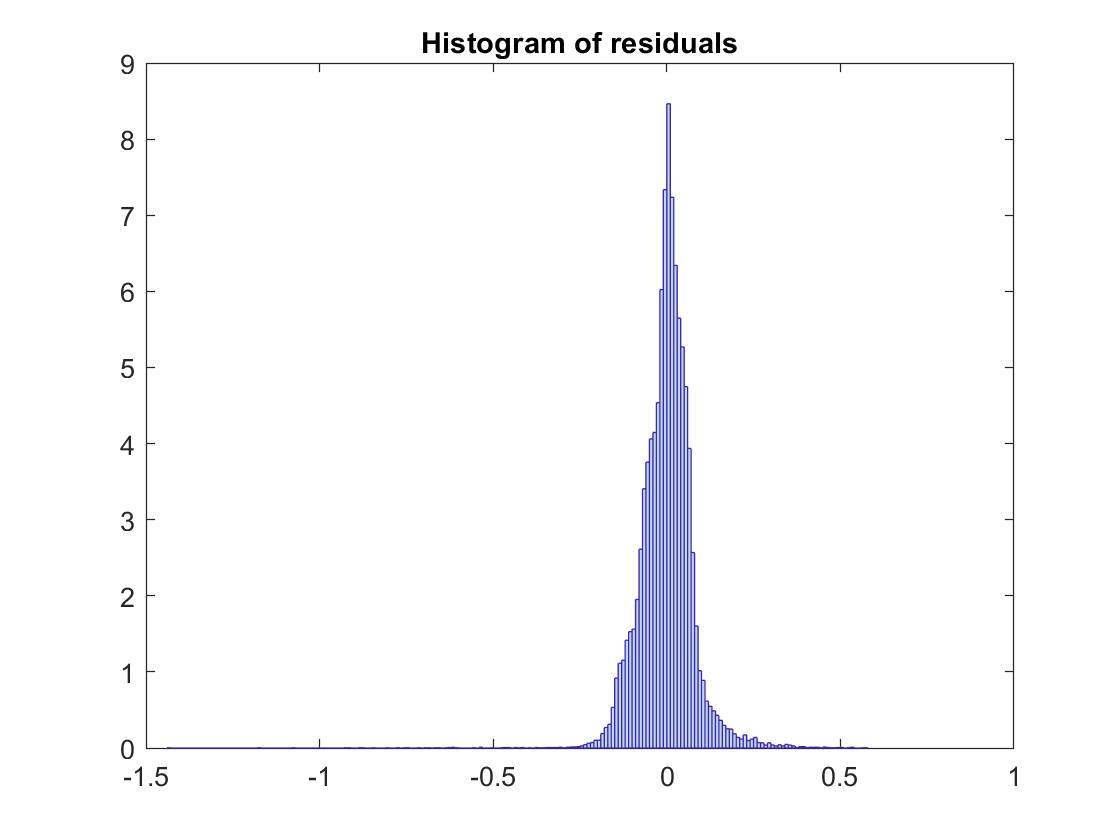

plotResiduals(mdlBase_FE)

This looks normally distributed, the model is valid.

## Model 1: conservative missing value treatment.

Following on from the approach to missing values from the EDA, first replacing missing values with that of the same property_id;

% get averages by property id
meanbyPropertyID = grpstats(Data(:,[{'property_id'},transformVarNames]),{'property_id'},'mean');
% indicies of property_id in averages table
[id,iL] = ismember(Data.property_id , meanbyPropertyID.property_id);

% Establish new, clean dataset
idnumericMissing = ismissing(Data{:,transformVarNames});
DataCln = Data;
% loop through numeric variables to replace missing values with those in different rows for the same property_id
for vi = transformVarNames
    iMiss = ismissing(Data.(vi{1}));
    DataCln{ iMiss&id , vi } = meanbyPropertyID{iL(iMiss&id),['mean_',vi{1}]};
end
missingRows2 = any(idnumericMissing,2);
sprintf('%0.0f rows cleaned', sum(missingRows2) - sum(any(ismissing( DataCln{:,transformVarNames} ),2)) )

ans = '1829 rows cleaned'

Building on Model 0's terms, and including the cleaned rows

% postcode as a random effect
mdlBase_ME1 = fitglme( DataCln(trainId & ~missingRows2,:) , ['log_sale_price ~ sqrt_max_roof_height:property_type + state*property_type + cube_year_built + sqrt_land*property_type + sqrt_floorplate*property_type + sale_date_numeric + bedrooms + bathrooms + garages'...
' + (1 | postcode )'] )

mdlBase_ME1 = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           33767
    Fixed effects coefficients          14
    Random effects coefficients        118
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    log_sale_price ~ 1 + bedrooms + bathrooms + garages + sale_date_numeric + cube_year_built + property_type*state + property_type*sqrt_land + property_type*sqrt_floorplate + property_type:sqrt_max_roof_height + (1 | postcode)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -80332    -80197    40182            -80364  
Fixed effects coefficients (95% CIs):
    Name                                               Estimate       SE            tStat      DF       pValue         Lower      

Again pValues are good. plotting Residuals;

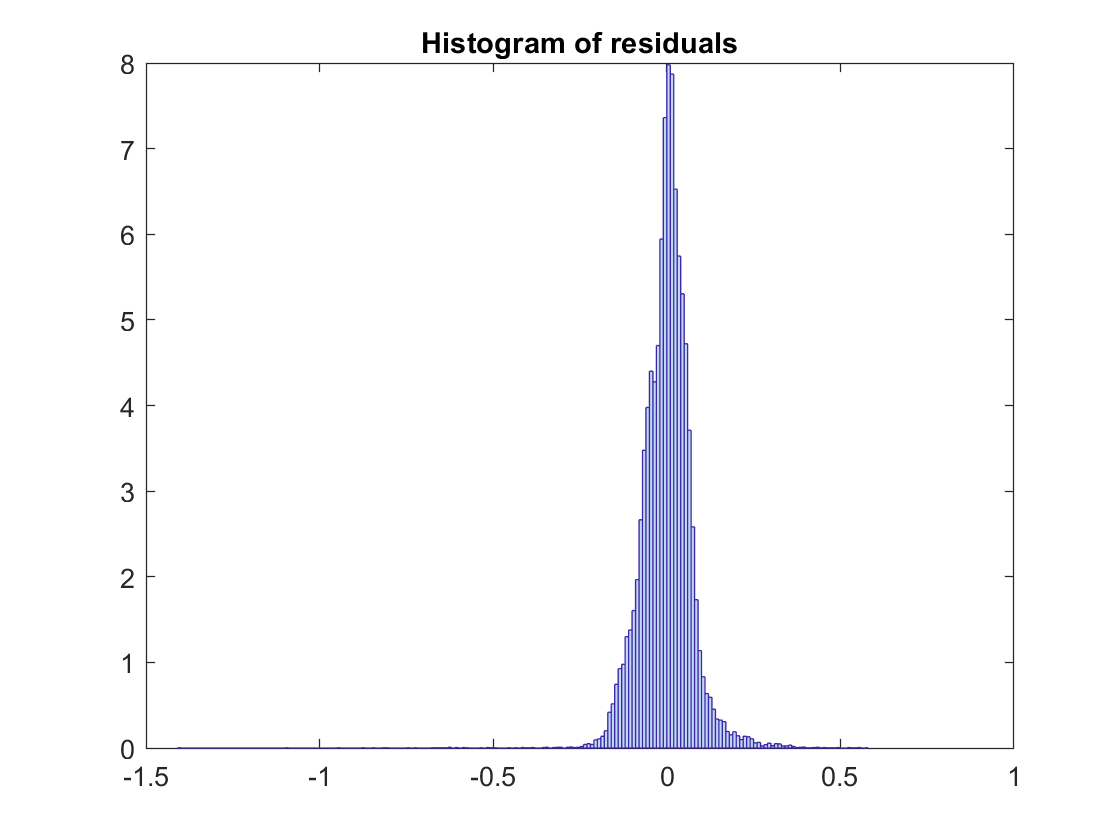

plotResiduals(mdlBase_ME1)

Residuals are normal, the model is valid.

The new term `postcode` has been designated a random variable, and this was seen to be normally distributed in the EDA. to asses whether the postcode term si significant, we have to conduct a null hypotheses test that this model is more likely than a model without the postcode term.

mdlBase_FE1 = fitglme( DataCln(trainId & ~missingRows2,:) , ['log_sale_price ~ sqrt_max_roof_height:property_type + state*property_type + cube_year_built + sqrt_land*property_type + sqrt_floorplate*property_type + sale_date_numeric + bedrooms + bathrooms + garages'...
' '] )

mdlBase_FE1 = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           33767
    Fixed effects coefficients          14
    Random effects coefficients          0
    Covariance parameters                1
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    log_sale_price ~ 1 + bedrooms + bathrooms + garages + sale_date_numeric + cube_year_built + property_type*state + property_type*sqrt_land + property_type*sqrt_floorplate + property_type:sqrt_max_roof_height

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -77481    -77354    38755            -77511  
Fixed effects coefficients (95% CIs):
    Name                                               Estimate       SE            tStat      DF       pValue         Lower          Upper      
 

compare(mdlBase_FE1 , mdlBase_ME1 )

ans =     Theoretical Likelihood Ratio Test

    Model          DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue
    mdlBase_FE1    15    -77481    -77354    38755                                
    mdlBase_ME1    16    -80332    -80197    40182     2853.4    1          0     

the model with postcode as a random variable fails the null hypotheses test, so `postcode` is a random effect seen in the data.

RMSE_ME1 = sqrt(nanmean( ( exp(predict( mdlBase_ME1 , DataCln(validateId,:) )) - exp(DataCln.log_sale_price(validateId)) ).^2 ))

RMSE_ME1 = 8.8921e+04

## Model 2: Imputed missing values

For this model, the remaining missing values will be replaced with average values in the same suburb. First "`Strata" `types, then "`House" type observations.`

% get averages by property id
idnumericMissing3 = ismissing(DataCln{:,transformVarNames});
missingRows3 = any(idnumericMissing3,2);
% Establish new, clean dataset
DataCln2 = DataCln;
% process missing values by property type
for ist = [DataCln.property_type=="Strata" , DataCln.property_type=="House"]
      meanbysuburbpostcode = grpstats(DataCln( ist ,[{'suburb','property_type'},transformVarNames]),{'suburb','property_type'},'mean');
      % indicies of suburb in averages table
      [id,iL] = ismember(DataCln.suburb , meanbysuburbpostcode.suburb);
      % loop over variables, impute from suburb average
      for vi = transformVarNames
            iMiss = ismissing(DataCln.(vi{1}));
            DataCln2{ iMiss&id &ist, vi } = meanbysuburbpostcode{iL(iMiss&id &ist),['mean_',vi{1}]};
      end
      sprintf('%0.0f rows cleaned', sum(missingRows3) - sum(any(ismissing( DataCln2{:,transformVarNames} ),2)) )
end

ans = '864 rows cleaned'

ans = '2164 rows cleaned'

Now that all missing values have been replaced with suburb averages, the same Model as above will be built, but with the new cleaning technique applied/

% postcode as a random effect. only 1 observation is missing from training set now;
mdlBase_ME2 = fitglme( DataCln2(trainId & ~missingRows3,:) , ['log_sale_price ~ sqrt_max_roof_height:property_type + state*property_type + cube_year_built + sqrt_land*property_type + sqrt_floorplate*property_type + sale_date_numeric + bedrooms + bathrooms + garages'...
' + (1 | postcode )'] )

mdlBase_ME2 = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           35042
    Fixed effects coefficients          14
    Random effects coefficients        118
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    log_sale_price ~ 1 + bedrooms + bathrooms + garages + sale_date_numeric + cube_year_built + property_type*state + property_type*sqrt_land + property_type*sqrt_floorplate + property_type:sqrt_max_roof_height + (1 | postcode)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -83430    -83294    41731            -83462  
Fixed effects coefficients (95% CIs):
    Name                                               Estimate       SE            tStat      DF       pValue         Lower      

Model has only very slightly different coefficients - to be expected as only 3% or so of nearly randomly missing values were added.

% Calculate Roomt Mean Square Error on the validation set, including the missing ros.
RMSE_ME2 = sqrt(nanmean( ( exp(predict( mdlBase_ME2 , DataCln2(validateId,:) )) - exp(DataCln2.log_sale_price(validateId)) ).^2 ))

RMSE_ME2 = 9.0038e+04

Interestingly, this model has a worse Root mean squared error, even though it has all of the missing values replaced with suburb averages.

## Model Selection

compare(mdlBase_ME1,mdlBase_ME2)

ans =     Theoretical Likelihood Ratio Test

    Model          DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue
    mdlBase_ME1    16    -80332    -80197    40182                                
    mdlBase_ME2    16    -83430    -83294    41731     3097.8    0          0     

RMSE_ME1_test = sqrt(nanmean( ( exp(predict( mdlBase_ME1 , Data(testId,:) )) - exp(Data.log_sale_price(testId)) ).^2 ))

RMSE_ME1_test = 1.6467e+05

RMSE_ME2_test = sqrt(nanmean( ( exp(predict( mdlBase_ME2 , Data(testId,:) )) - exp(DataCln.log_sale_price(testId)) ).^2 ))

RMSE_ME2_test = 1.6519e+05

RMSE_FE_test = sqrt(nanmean( ( exp(predict( mdlBase_FE , Data(testId,:) )) - exp(DataCln.log_sale_price(testId)) ).^2 ))

RMSE_FE_test = 1.8659e+05